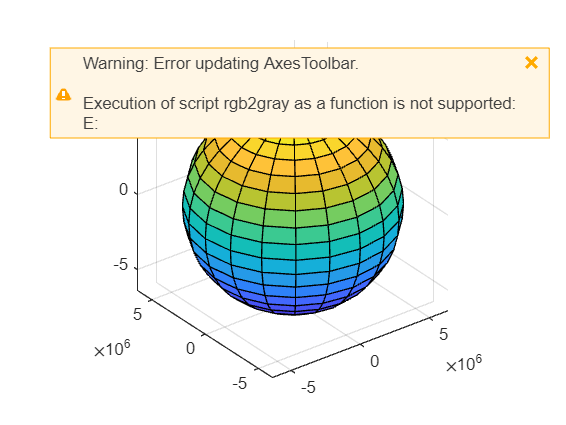

[x,y,z] = sphere;
x = x*6378000;
y = y*6378000;
z = z*6357000;
surf(x,y,z)
axis equal
hold on

Re = 6378000;
R = 7178000;
Me = 5.97219*(10^24);
G = 6.6743*(10^-11);
J2 = 1.08263*(10^-3);
T = (1:6000)';
M = zeros(length(T), 3);
Theta = zeros(length(T), 1);
Omega = sqrt((G*Me)/R);
% Theta = linspace(0,2*pi,length(T));
h = 1;
for v = 2:length(T)
    Theta(v)=Theta(v-1) + h*Omega;
end
% Phi(1:length(T)/2) = linspace(pi/5,(-pi/5),length(T)/2);
% Phi(length(T)/2+1:length(T)) = linspace(-pi/5,pi/5,length(T)/2);
M(:,1) = R*cos(Theta);
M(:,2) = R*sin(Theta);
M(:,3) = 0;
% P = rotx(i);
% N = M*P;
% plot3(N(:,1), N(:,2), N(:,3))
% hold on
% p = plot3(M(:,1), M(:,2), M(:,3), 'o','MarkerFaceColor','red');
% hold off
% axis manual
% for k = 2:length(T)
%     p.XData = M(k,1);
%     p.YData = M(k,2);
%     p.ZData = M(k,3);
%     drawnow
% end
dt = 10000;
i = 72;
Wp = zeros(100,1);
p = zeros(100,1);
for v = 1:99
     hold on
    P = rotx(i);
    Q = rotz(p(v));
    N = M*P;
    N = N*Q;
    A = plot3(N(:,1), N(:,2), N(:,3), "blue");
    Wp(v) = (-1.5)*((Re/R)^2)*(J2*Omega*cos(i*(pi/180)));
    p(v+1) = p(v) + Wp(v)*dt;
    pause(0.1)
    delete(A)
end